McCabe-Thiel Graph

x=liquid mole fraction

y=vapor mole fraction

Equilibrium Data (Ethanol-Water)

% The below values may change depending on compound being analyzed
num=readtable('file.xlsx');

Xdata=table2array(num(:,2));
Ydata=table2array(num(:,3));
Xwater=1-Xdata;
Ywater=1-Ydata;


Basic Graph

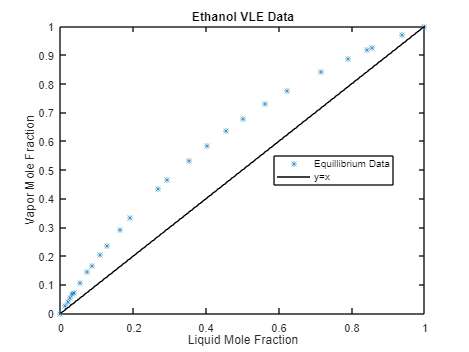

plot(Xdata,Ydata,"*",'DisplayName','Equillibrium Data');
legend('Location','best')
title("Ethanol VLE Data")
xlabel("Liquid Mole Fraction")
ylabel("Vapor Mole Fraction")
hold on
plot(0:1,0:1,"k",'DisplayName','y=x');

Best-Fit Line for Equillibrium Data

 (best fit function)

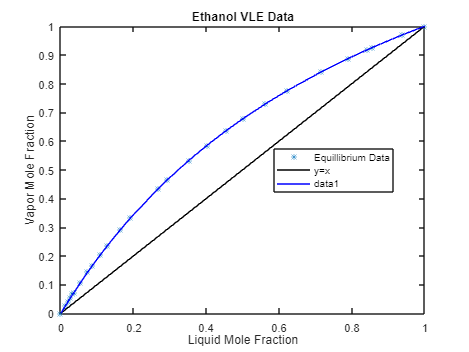

n=6; %The higher the n value, the better the fit for the data
f=polyfit(Xdata,Ydata,n);
hold on
yfit=polyval(f,Xdata);
plot(Xdata,yfit,"b-");

Zf, XD and XB lines

hold on
% Zf is mole fraction of the more volatile component
Zf=0.43;
plot([Zf Zf],[0 1],"g--",'DisplayName','Zf')
XD=0.995;
% XD is desired distilate
XB=0.005;
% XB is desired bottoms product
hold on
plot([XB XB],[0 1],"g--",'DisplayName','XB');
hold on
plot([XD XD],[0 1],"g--",'DisplayName','XD');

q-line

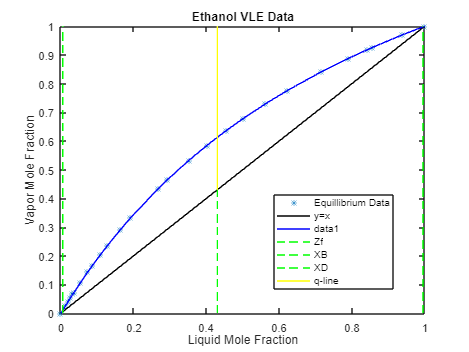

% ql is the mole fraction of liquid, q is the q-line slope
q=1;

if q==1
   plot([Zf Zf],[Zf q],"y-",'DisplayName','q-line');
xlim([0.000 1.000])
ylim([0.000 1.000])
elseif q==0
    plot([0 Zf],[Zf Zf],"y-",'DisplayName','q-line');
    xlim([0.000 1.000])
    ylim([0.000 1.000])
else
    %x=linspace(0,1);
    x=[Zf,0];
    y=((-q/(1-q))*x)+(Zf/(1-q));
    hold on
    plot(x,y,"y-",'DisplayName','q-line');
    xlim([0.000 1.000])
ylim([0.000 1.000])
end

Pinch Point

% R=Reflux ratio, which is equivalent to L/V
% R_min=L/D
% R_total_reflux=1, gives line of y=x
% R_operating=R/R+1
if q==1
    pinch_point_x=Zf;
pinch_point_y=polyval(f, Zf);
elseif q==0
pinch_point_y=double(Zf);
pinch_point_x=fzero(@(x) polyval(f, x)-pinch_point_y,[0 1]);
else
    syms x
pinch_point=solve(poly2sym(f, sym(x)) - ((-q/(1 - q)) * x + Zf / (1 - q)), x);
pinch_point_x=double(pinch_point(1));
pinch_point_y=polyval(f,pinch_point_x);
end
R_min=(XD-pinch_point_y)/(pinch_point_y-pinch_point_x);
R_min=R_min+0.006

R_min = 2.0930

R_min=round(R_min,3)

R_min = 2.0930

Intersection point of Rectification line and q-line

disp("Minimum value for R_operating is: "+ R_min +"    Maximum value for R_operating is: 100")

Minimum value for R_operating is: 2.093    Maximum value for R_operating is: 100


R_operating=3.13;
if q==1
    solx = Zf;
else
syms x
solx = double(solve((R_operating*x)/(R_operating+1)+(XD/(R_operating+1)) == ((-q/(1-q))*x)+(Zf/(1-q)), x));
% solx is the intersection point between the q-line and rectification line
end

Rectification Section Operating-Line

xr=[solx,XD];
yr=((R_operating*xr)/(R_operating+1))+(XD/(R_operating+1));
plot(xr,yr,"r",'DisplayName','Rectification Line')

Stripping Section Operating line

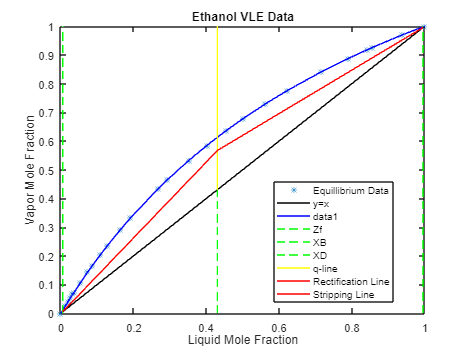

hold on
plot([XB solx],[XB yr(:,1)],"r-",'DisplayName','Stripping Line');

Number of Stages for Column

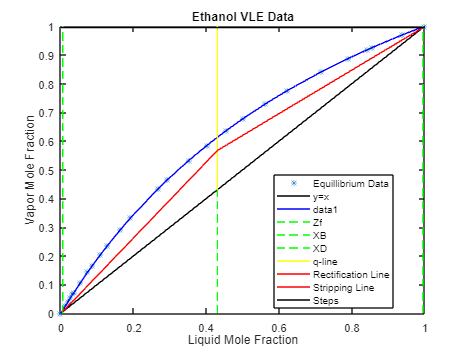

Xstep=XD;
Ystep=yr(:,2);
plot(0:1,[Ystep,Ystep],"k-",DisplayName="Steps");
legend('AutoUpdate','off');

Vertical Lines

%sol=roots(f(end)-XD)
step_y=XD; %initial conditions
sol=XD; %initial conditions
step_count=0; %initial conditions
while sol>XB

    polyfunc=@(x) polyval(f, x)-step_y; % step_y is the y-value on the fit curve
    sol=fzero(polyfunc,[0 1]); %sol yields the x-value on the fit curve
    hold on


Horizontal sections

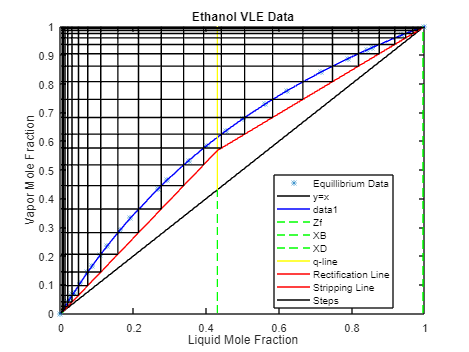

    if sol>solx
        step_y=((R_operating*sol)/(R_operating+1))+(XD/(R_operating+1)); %the y-value for when the rectification line intersects sol
    elseif sol<=solx
        x_int=yr(1,1)-(((yr(1,1)-XB)/(solx-XB))*solx);
        step_y=(((yr(1,1)-XB)/(solx-XB))*sol)+x_int;
    end
    hold on
    plot([0 sol],[step_y step_y],"k-") % horizonatal lines
    plot([sol sol],[step_y 1],"k-") % vertical lines
    step_count=(step_count)+1;
    for k=step_count
        x_concentration(k)=sol;

        y_concentration(k)=step_y;
    end
end

steps=step_count;
disp("Number of Steps: "+steps)

Number of Steps: 25


Find data for a specific stage 

% Can view full data in table below
stage=1;
if stage==1
    Liquid_Mole_Fraction=x_concentration(1);
    Vapor_Mole_Fraction=XD;
else
       Liquid_Mole_Fraction=x_concentration(stage);
        Vapor_Mole_Fraction=y_concentration(stage-1);
end
disp("Liquid_Mole_Fraction: "+ Liquid_Mole_Fraction);

Liquid_Mole_Fraction: 0.98955


disp("Vapor_Mole_Fraction: " + Vapor_Mole_Fraction);

Vapor_Mole_Fraction: 0.995


Displaying Concentrations at different stages

stage_number=1:steps;
Liquid_Mole_Fraction = zeros(1, steps);
Vapor_Mole_Fraction = zeros(1, steps);
for stage=1:steps
    if stage==1
    Liquid_Mole_Fraction(stage)=x_concentration(1);
    Vapor_Mole_Fraction(stage)=XD;
    else
       Liquid_Mole_Fraction(stage)=x_concentration(stage);
        Vapor_Mole_Fraction(stage)=y_concentration(stage-1);
    end

end
table_of_concentrations=table(stage_number',Liquid_Mole_Fraction',Vapor_Mole_Fraction',VariableNames=["stage_number" "Liquid_Mole_Fraction","Vapor_Mole_Fraction"]) 

table_of_concentrations = 25×3 table
    stage_number    Liquid_Mole_Fraction    Vapor_Mole_Fraction
    ____________    ____________________    ___________________

          1               0.98955                   0.995      
          2               0.98098                 0.99087      
          3                0.9677                 0.98438      
          4               0.94748                 0.97431      
          5               0.91754                 0.95899      
          6               0.87498                  0.9363      
          7               0.81775                 0.90404      
          8                0.7463                 0.86066      
          9               0.66498                 0.80652      
         10               0.58164                 0.74489      
         11               0.50494                 0.68173      
         12               0.